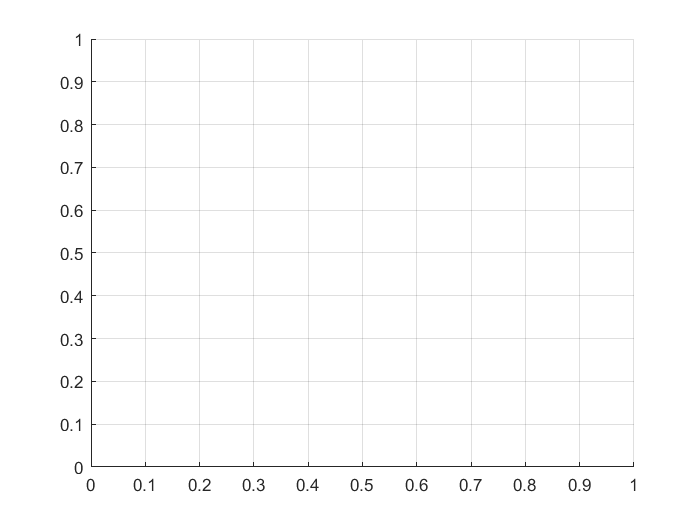

%skrypt do generowania trajektorii fazowych:
%Nazwa do wywołania: tr_faz
%Tu wpisujemy macierz stanu:
A = [-1, 0; 0, -2];
T=6; %czas końcowy
[w, J]=eig(A); %wektory i wartości własne
figure;hold on; grid on;

%Wyznaczanie zbioru warunków poczakowych obejmujących wszystkie 4 ćwiartki
%płaszczyzny fazowej:
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
%cykliczne wywoływanie modelu simulinkowego wraz rysowaniem trajektorii:
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T); %W tym miejscu jest wykonywany model simulinkowy
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

No system or file called 'traj_fazowe' found.

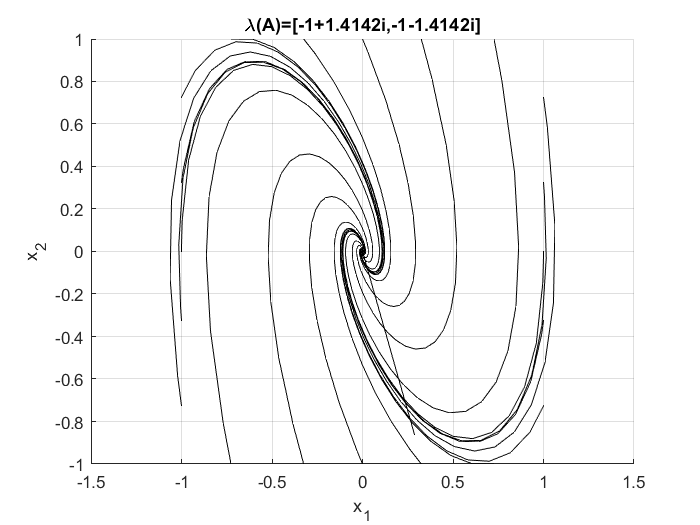


A = [0, 1; -3, -2];
T=6; [w, J]=eig(A); figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

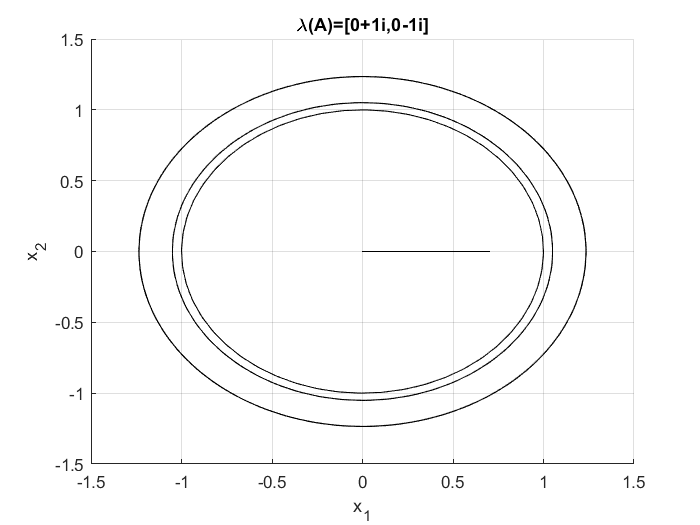


A = [0, 1; -1, 0];
T=6; [w, J]=eig(A); figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

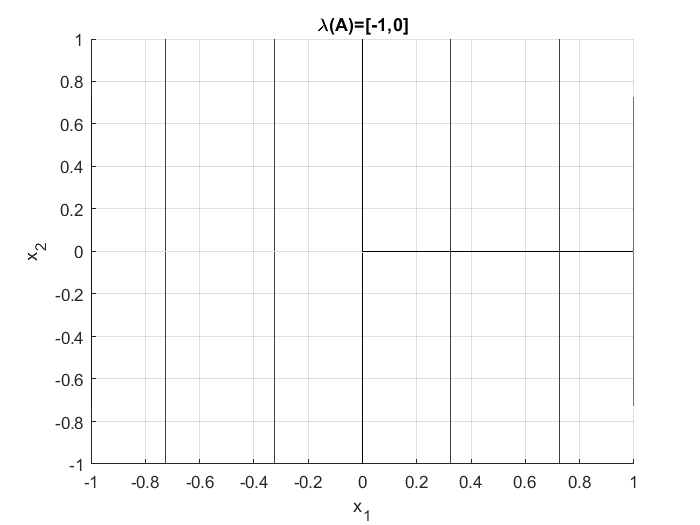


A = [0, 0; 0, -1];
T=6; [w, J]=eig(A); figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

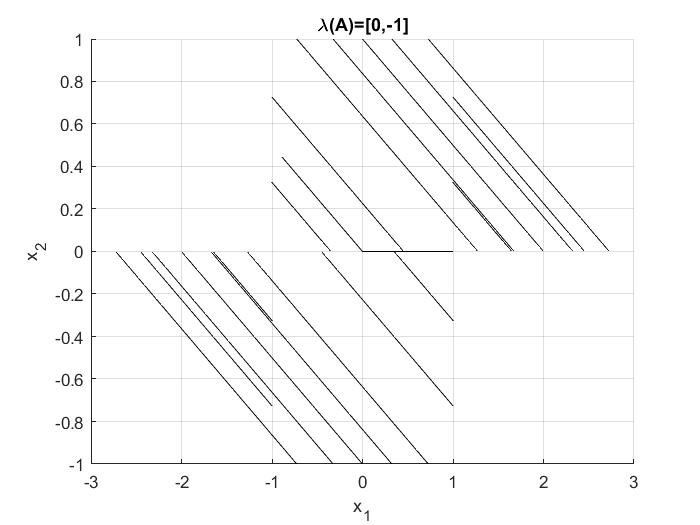


A = [0, 2; 0, -1];
T=6; [w, J]=eig(A); figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

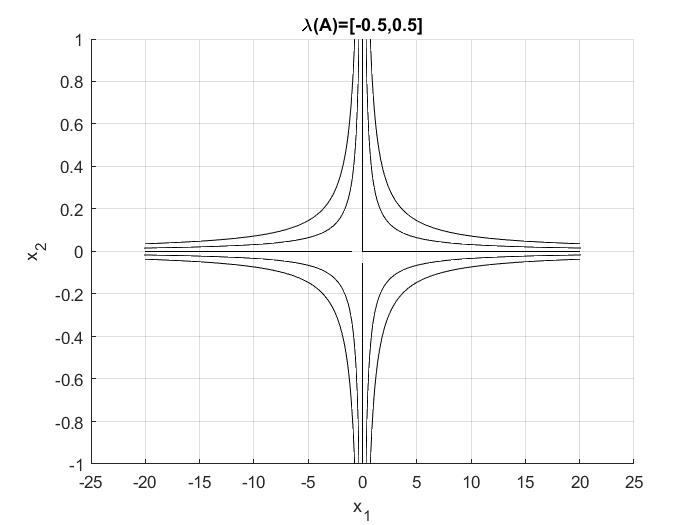


A = [0.5, 0; 0, -0.5];
T=6; [w, J]=eig(A); figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

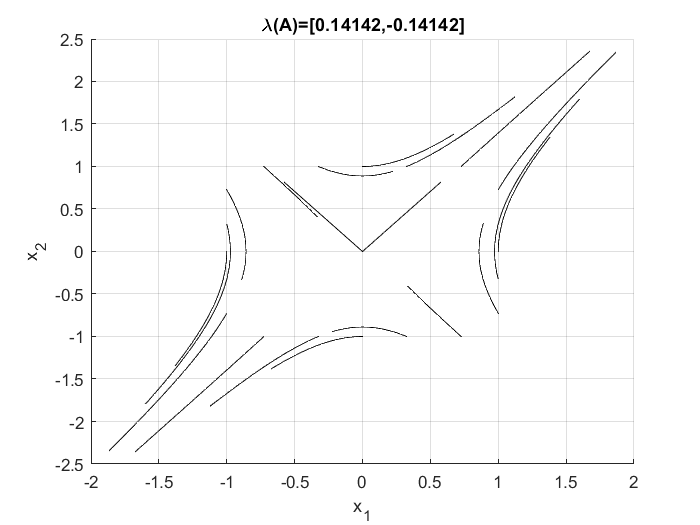


A = [0, 0.1; 0.2, 0];
T=6; [w, J]=eig(A); figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end

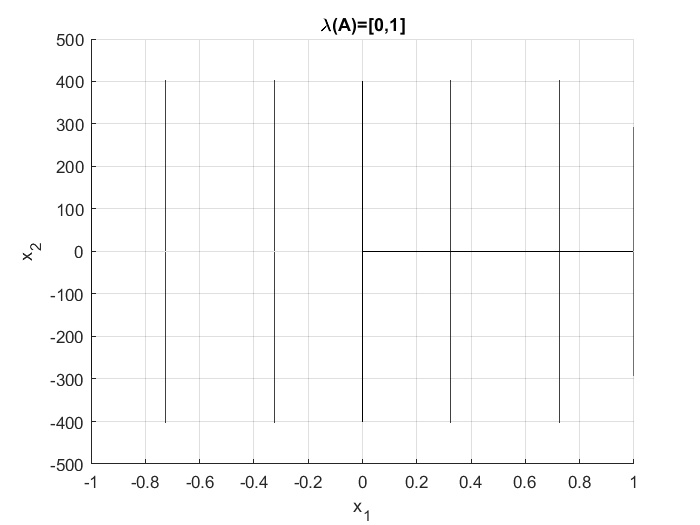


A = [0, 0; 0, 1];
T=6; [w, J]=eig(A); figure;hold on; grid on;
a=0:(pi/10):(2*pi);X1=[cos(a);sin(a)];
X2=X1./[max(abs(X1));max(abs(X1))];M=size(X2,2);
for m=1:M
 x0=X2(:,m);
 sim('traj_fazowe',T);
 plot(ans.x(:,1),ans.x(:,2),'k-');
 plot([0,w(1,1)],[0,w(2,1)],'k-',[0,w(1,2)],[0,w(2,2)],'k-');
 title(['\lambda(A)=[',num2str(J(1,1)),',',num2str(J(2,2)),']'] );
 xlabel('x_1');ylabel('x_2');
end